# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

RA = 6.4/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.008; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 5;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 6;
gamma_vreft = 360+70;
alpha_vreft = 0.1;

% position to pre velocity controller
gamma_xvref = 360+60;
alpha_xvref = 0.1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  5.351e05 s^3 + 5.351e08 s^2 - 3.873e07 s - 3.873e10
  -----------------------------------------------------------------------------------
  s^6 + 2888 s^5 + 2.213e06 s^4 + 3.435e08 s^3 + 1.417e09 s^2 - 5.737e10 s - 1.306e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf(2.183,[1 6.651]);

## Bodeplot

pole(Gvu)

ans = -6.6510

isstable(Gvu)

ans = logical
   1


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


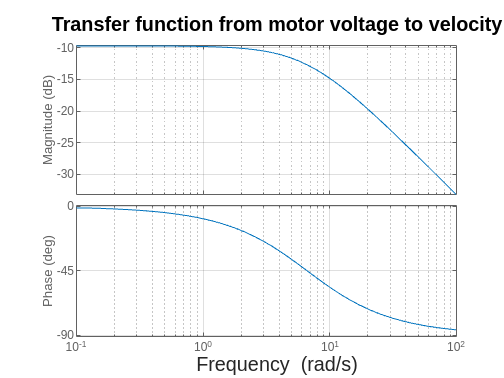

bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

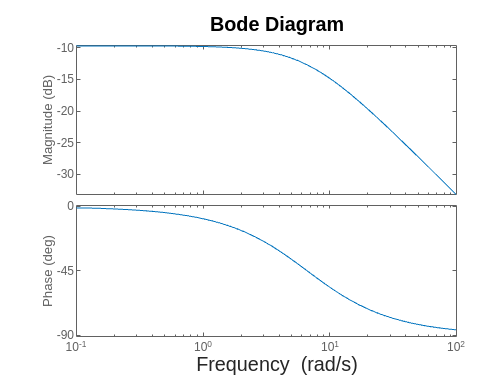

% Design parameters
N_i = N_i_vu;
gamma_m = gamma_vu;

phi_i = rad2deg(-atan(1/N_i));
phi_G = -180+gamma_m-phi_i;

bode(Gvu)

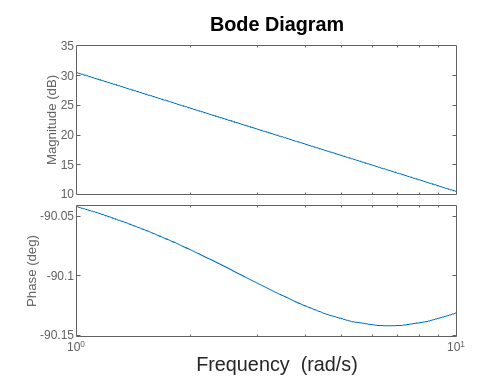


[mag,phase,wout] = bode(Gvu);
omega_c = interp1(squeeze(phase),wout,phi_G);
tau_i = N_i/omega_c;
C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

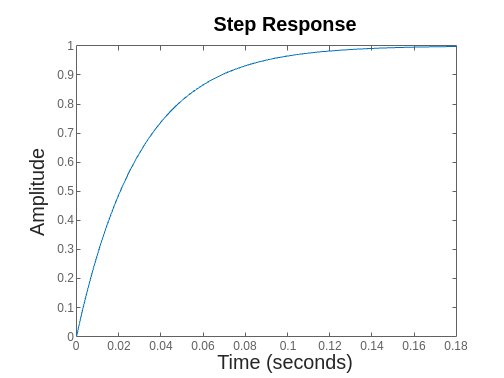

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 15.3064

t_i_vu = tau_i

t_i_vu = 0.1496

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -4.581e05 s^4 - 5.933e08 s^3 - 1.037e11 s^2 - 6.669e11 s - 1.996e09
  -------------------------------------------------------------------------------------------------
  s^7 + 2888 s^6 + 2.213e06 s^5 + 3.517e08 s^4 + 9.662e09 s^3 - 3.22e09 s^2 - 7.273e11 s - 3.962e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


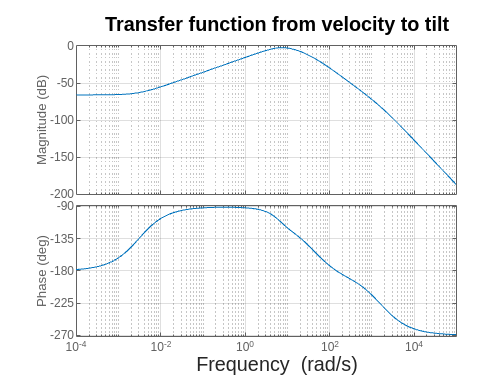

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.7636

fpeak = 7.4151

tau_i = 1/fpeak

tau_i = 0.1349

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1349 s - 1
  -------------
    0.1349 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
                6.178e04 s^5 + 8.047e07 s^4 + 1.457e10 s^3 + 1.936e11 s^2 + 6.672e11 s + 1.996e09
  --------------------------------------------------------------------------------------------------------------
  0.1349 s^8 + 389.5 s^7 + 2.984e05 s^6 + 4.743e07 s^5 + 1.303e09 s^4 - 4.342e08 s^3 - 9.809e10 s^2 - 5.344e11 s
 
Continuous-time transfer function.


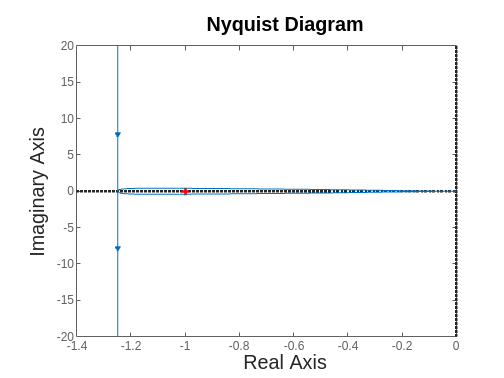

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                  4.581e05 s^5 + 5.967e08 s^4 + 1.081e11 s^3 + 1.436e12 s^2 + 4.947e12 s + 1.48e10
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 2888 s^7 + 2.213e06 s^6 + 3.522e08 s^5 + 1.026e10 s^4 + 1.049e11 s^3 + 7.083e11 s^2 + 9.847e11 s + 1.48e10
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1349

## Tilt to velocity controller PI-lead

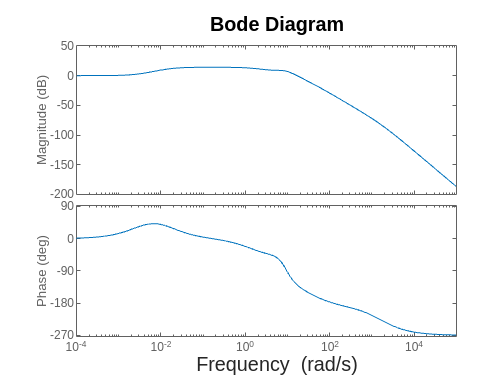

bode(G_post_cl)

% Design parameters
N_i = N_i_tv;
gamma_m = gamma_tv;
alpha = alpha_tv;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.01592 s + 1
  -------------
    0.01592 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.5035 s + 1
  ---------------
  5.035e-06 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
              2.058e11 s^7 + 2.814e14 s^6 + 6.593e16 s^5 + 3.823e18 s^4 + 5.005e19 s^3 + 2.244e20 s^2 + 2.776e20 s + 8.292e17
  ----------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.015e05 s^9 + 5.758e08 s^8 + 4.398e11 s^7 + 6.995e13 s^6 + 2.037e15 s^5 + 2.082e16 s^4 + 1.407e17 s^3 + 1.956e17 s^2 + 2.94e15 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                    2.058e11 s^7 + 2.814e14 s^6 + 6.593e16 s^5 + 3.823e18 s^4 + 5.005e19 s^3 + 2.244e20 s^2 + 2.776e20 s + 8.292e17
  ----------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.015e05 s^9 + 5.758e08 s^8 + 6.456e11 s^7 + 3.513e14 s^6 + 6.797e16 s^5 + 3.844e18 s^4 + 5.019e19 s^3 + 2.246e20 s^2 + 2.776e20 s + 8.292e17
 
Continuous-time transfer function.


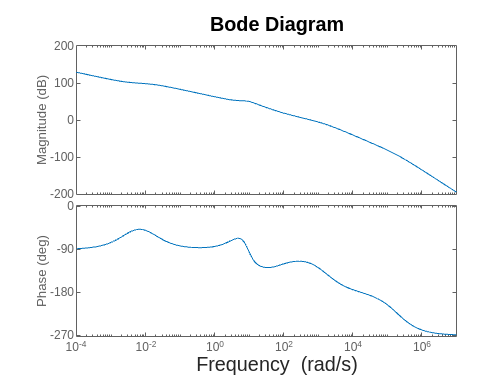


bode(G_tv_ol)

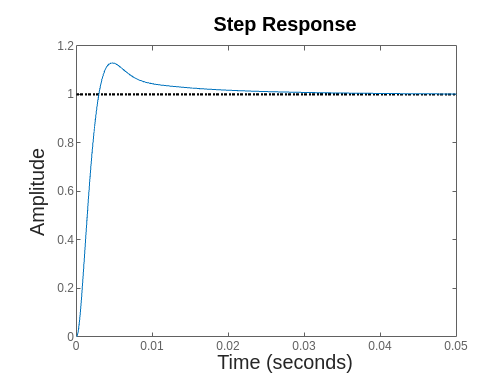

step(G_tv_cl)

## Flush values to simulink

t_lead_tv = tau_D;
t_i_tv = tau_i;
K_tv = Kp;

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                -3.679e07 s^6 - 3.962e10 s^5 - 2.861e12 s^4 - 3.165e13 s^3 + 9.274e13 s^2 + 2.498e15 s + 8.288e15
  ------------------------------------------------------------------------------------------------------------------------------
  s^9 + 2888 s^8 + 3.249e06 s^7 + 1.76e09 s^6 + 3.334e11 s^5 + 1.919e13 s^4 + 2.519e14 s^3 + 1.13e15 s^2 + 1.398e15 s + 4.175e12
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


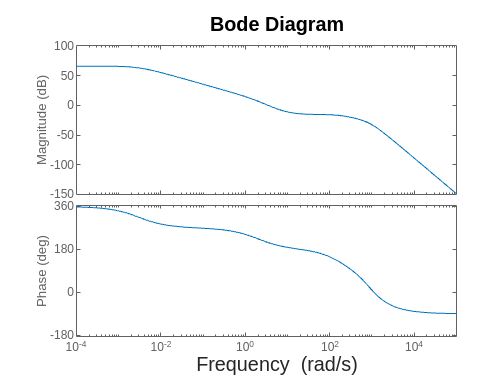

bode(G_vreft)



% Design parameters
N_i = N_i_vreft;
gamma_m = gamma_vreft;
alpha = alpha_vreft;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  1.442 s + 1
  -----------
    1.442 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.7601 s + 1
  -------------
  0.07601 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
             -1.505e08 s^8 - 1.624e11 s^7 - 1.203e13 s^6 - 1.532e14 s^5 + 1.086e14 s^4 + 1.087e16 s^3 + 5.479e16 s^2 + 7.745e16 s + 3.093e16
  -----------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2901 s^10 + 3.287e06 s^9 + 1.803e09 s^8 + 3.566e11 s^7 + 2.358e13 s^6 + 5.044e14 s^5 + 4.444e15 s^4 + 1.626e16 s^3 + 1.839e16 s^2 + 5.493e13 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                  -1.505e08 s^8 - 1.624e11 s^7 - 1.203e13 s^6 - 1.532e14 s^5 + 1.086e14 s^4 + 1.087e16 s^3 + 5.479e16 s^2 + 7.745e16 s + 3.093e16
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2901 s^10 + 3.287e06 s^9 + 1.653e09 s^8 + 1.942e11 s^7 + 1.155e13 s^6 + 3.513e14 s^5 + 4.553e15 s^4 + 2.713e16 s^3 + 7.318e16 s^2 + 7.751e16 s + 3.093e16
 
Continuous-time transfer function.


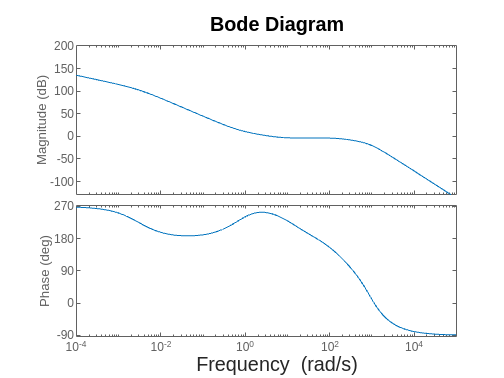


bode(G_vreft_ol)

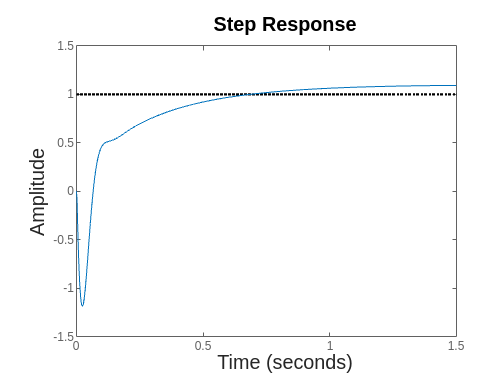

step(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i;
[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v');
K_vreft = Kp;

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
             -7.527e04 s^9 - 9.722e07 s^8 - 2.347e10 s^7 - 1.559e12 s^6 - 3.121e13 s^5 - 1.666e14 s^4 + 1.426e15 s^3 + 1.938e16 s^2 + 6.922e16 s + 6.435e16
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2901 s^11 + 3.287e06 s^10 + 1.661e09 s^9 + 2.024e11 s^8 + 1.159e13 s^7 + 3.425e14 s^6 + 4.432e15 s^5 + 2.723e16 s^4 + 8.121e16 s^3 + 1.13e17 s^2 + 6.435e16 s
 
Continuous-time transfer function.


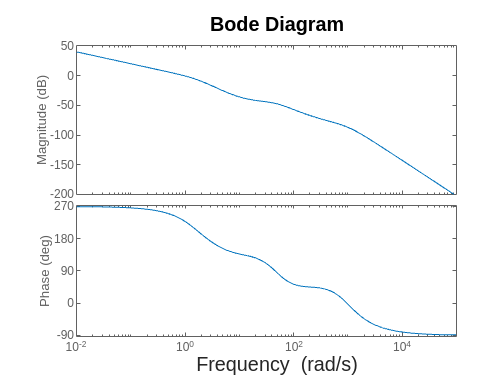

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.2101 + 0.0000i
  -0.7734 + 0.6405i
  -0.7734 - 0.6405i
  -0.0528 + 0.0000i
  -0.0356 + 0.0338i
  -0.0356 - 0.0338i
  -0.0077 + 0.0000i
  -0.0064 + 0.0000i
  -0.0037 + 0.0000i




% Design parameters
gamma_m = gamma_xvref;
alpha = alpha_xvref;

phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  1.362 s + 1
  ------------
  0.1362 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
             -9.459e05 s^10 - 1.222e09 s^9 - 2.958e11 s^8 - 1.981e13 s^7 - 4.066e14 s^6 - 2.382e15 s^5 + 1.637e16 s^4 + 2.566e17 s^3 + 1.049e18 s^2 + 1.447e18 s + 5.938e17
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2909 s^12 + 3.308e06 s^11 + 1.685e09 s^10 + 2.146e11 s^9 + 1.308e13 s^8 + 4.276e14 s^7 + 6.947e15 s^6 + 5.979e16 s^5 + 2.812e17 s^4 + 7.094e17 s^3 + 8.941e17 s^2 + 4.726e17 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                  -9.459e05 s^13 - 1.243e09 s^12 - 3.221e11 s^11 - 2.633e13 s^10 - 8.761e14 s^9 - 1.421e16 s^8 - 1.037e17 s^7 + 9.801e16 s^6 + 8.178e18 s^5 + 6.887e19 s^4 + 2.837e20 s^3 + 6.106e20 s^2 + 6.115e20 s + 2.138e20
  -----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^16 + 2930 s^15 + 3.371e06 s^14 + 1.755e09 s^13 + 2.499e11 s^12 + 1.76e13 s^11 + 7.144e14 s^10 + 1.729e16 s^9 + 2.641e17 s^8 + 2.669e18 s^7 + 1.843e19 s^6 + 8.861e19 s^5 + 2.978e20 s^4 + 6.853e20 s^3 + 1.004e21 s^2 + 7.816e20 s + 2.138e20
 
Continuous-time transfer function.


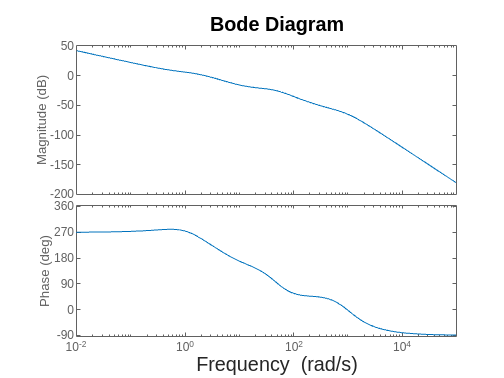


bode(G_xvref_ol)

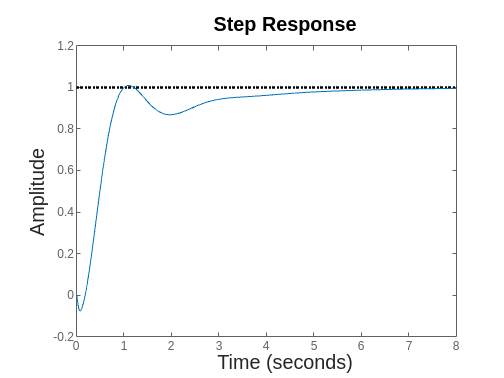

step(G_xvref_cl)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v');
K_xvref = Kp;

## Simulation for plots

regsim = sim(model,10);

## Plots

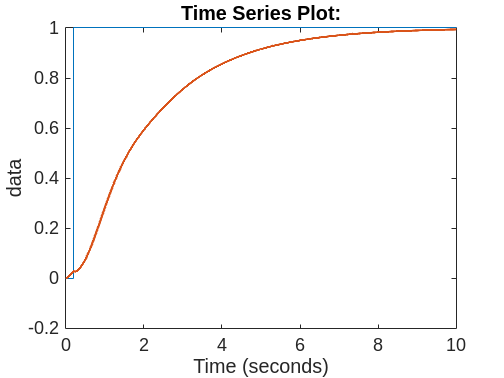

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;